# Earthquakes - ANOVA

## 1.

 Get a look at the boxplot of earthquake magnitudes grouped by country.

load quakes14.mat
quakes

quakes = 1704×12 table
            YEAR    MONTH    DAY    HOUR    MINUTE    MAGNITUDE        COUNTRY         COUNTRYCODE    LATITUDE    LONGITUDE    DEATHS    DAMAGECOST
            ____    _____    ___    ____    ______    _________    ________________    ___________    ________    _________    ______    __________
    2566    1900      1      11       9        7         NaN       JAPAN                   JP           36.5         133.5      NaN         NaN    
    2567    1900      1      14     NaN      NaN         NaN       INDONESIA               

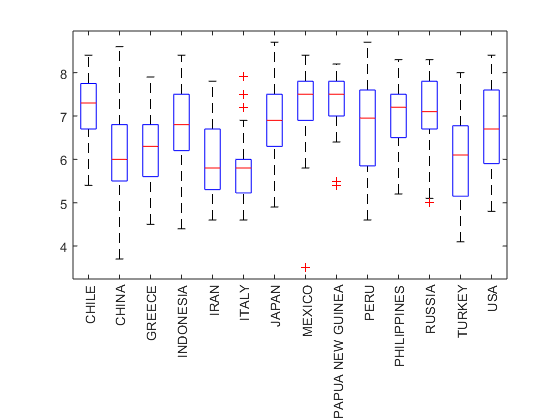

boxplot(quakes.MAGNITUDE,quakes.COUNTRY)
xtickangle(90)

## 2.

From the boxplot it appears that there are differences between countries. Verify this by performing an ANOVA.

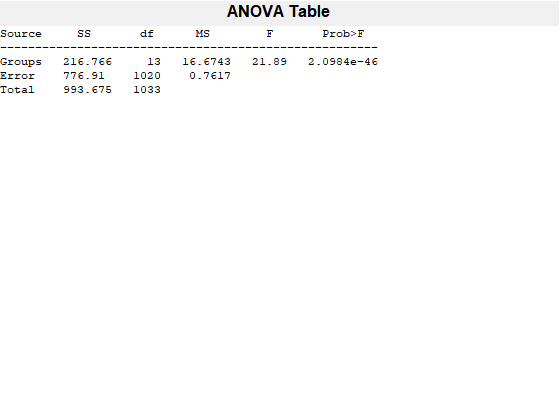

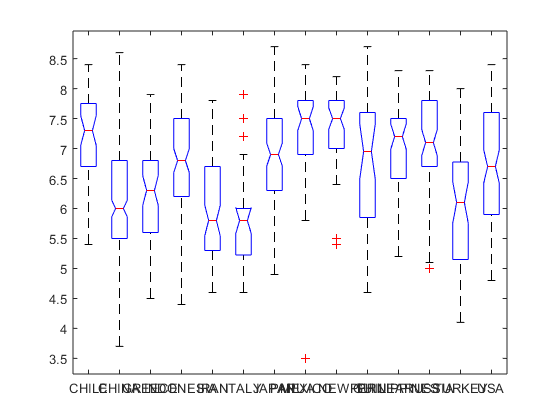

p = 2.0984e-46

stat = struct with fields:
    gnames: {14×1 cell}
         n: [44 219 58 107 74 31 98 50 50 36 55 63 55 94]
    source: 'anova1'
     means: [1×14 double]
        df: 1020
         s: 0.8727

[p,~,stat] = anova1(quakes.MAGNITUDE,quakes.COUNTRY)

## 3.

Use the output from the ANOVA to perform a multiple comparison of means.

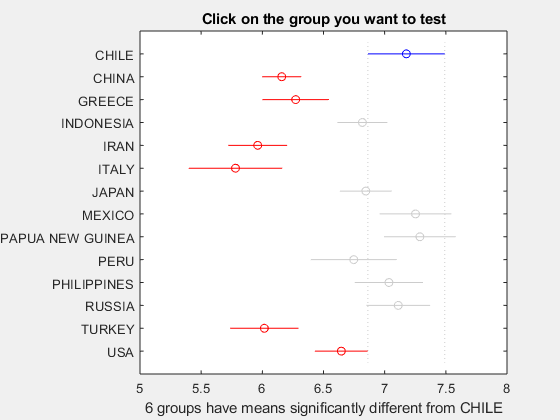

c =     1.0000    2.0000    0.5353    1.0188    1.5024    0.0000
    1.0000    3.0000    0.3197    0.9049    1.4900    0.0000
    1.0000    4.0000   -0.1647    0.3595    0.8837    0.5548
    1.0000    5.0000    0.6579    1.2151    1.7723    0.0000
    1.0000    6.0000    0.7103    1.3966    2.0829    0.0000
    1.0000    7.0000   -0.1998    0.3314    0.8625    0.7070
    1.0000    8.0000   -0.6797   -0.0747    0.5303    1.0000
    1.0000    9.0000   -0.7157   -0.1107    0.4943    1.0000
    1.0000   10.0000   -0.2277    0.4301    1.0878    0.6351
    1.0000   11.0000   -0.4493    0.1427    0.7347    0.9999


figure('Visible','on')
c = multcompare(stat)

## 4.

Find the country with the lowest mean magnitude. (**Hint: **Use `grpstats` to compute the mean magnitude for the quakes grouped by country.) 

Use the multiple comparison output to determine which countries have significantly different means from the lowest mean.

**Bonus: **Use logical indexing to determine the countries with significantly different means from the lowest mean programmatically.

S = grpstats(quakes,'COUNTRY',@mean,'DataVars','MAGNITUDE')

S = 14×3 table
                            COUNTRY         GroupCount    mean_MAGNITUDE
                        ________________    __________    ______________
    CHILE               CHILE                   89            7.1773    
    CHINA               CHINA                  227            6.1584    
    GREECE              GREECE                  86            6.2724    
    INDONESIA           INDONESIA              168            6.8178    
    IRAN                IRAN                   142            5.9622    
    ITALY               ITALY                  110            5.7806    
    JAPAN               JAPAN                  176            6.8459    
    MEXICO              MEXICO                  83             7.252    
    PAPUA

[~,idx] = min(S.mean_MAGNITUDE);
ctry_min_mean = char(S.COUNTRY(idx))

ctry_min_mean = 'ITALY'


% BONUS:
ctrys = categories(quakes.COUNTRY);
row_idx = (c(:,1) == idx | c(:,2) == idx) & c(:,3).*c(:,5) > 0;
ctrys_diff_min = ctrys(c(row_idx,1) + c(row_idx,2) - idx)

ctrys_diff_min = 9×1 cell array
    {'CHILE'           }
    {'INDONESIA'       }
    {'JAPAN'           }
    {'MEXICO'          }
    {'PAPUA NEW GUINEA'}
    {'PERU'            }
    {'PHILIPPINES'     }
    {'RUSSIA'          }
    {'USA'             }

## 5.

Repeat step 4 for the highest mean magnitude.

[~,idx] = max(S.mean_MAGNITUDE);
ctry_max_mean = char(S.COUNTRY(idx))

ctry_max_mean = 'PAPUA NEW GUINEA'


% BONUS:
row_idx = (c(:,1) == idx | c(:,2) == idx) & c(:,3).*c(:,5) > 0;
ctrys_diff_max = ctrys(c(row_idx,1) + c(row_idx,2) - idx)

ctrys_diff_max = 6×1 cell array
    {'CHINA' }
    {'GREECE'}
    {'IRAN'  }
    {'ITALY' }
    {'TURKEY'}
    {'USA'   }

## 6.

Are there any countries “in the middle”? That is, do any countries have means significantly different to both the lowest and highest means?

middle_ctrys = intersect(ctrys_diff_max,ctrys_diff_min)

middle_ctrys = 1×1 cell array
    {'USA'}